clc
clear all
close all

sz = [600 3];
varTypes = ["string","cell", "cell"];
varNames = ["FileName","ABB", "CEJ"];
dotLabels = table('Size',sz,'VariableTypes',varTypes,'VariableNames',varNames)

dotLabels = 600×3 table
    FileName         ABB             CEJ     
    _________    ____________    ____________

    <missing>    {0×0 double}    {0×0 double}
    <missing>    {0×0 double}    {0×0 double}
    <missing>    {0×0 double}    {0×0 double}
    <missing>    {0×0 double}    {0×0 double}
    <missing>    {0×0 double}    {0×0 double}
    <missing>    {0×0 double}    {0×0 double}
    <missing>    {0×0 double}    {0×0 double}
    <missing>    {0×0 double}    {0×0 double}
    <missing>    {0×0 double}    {0×0 double}
    <missing>    {0×0 double}    {0×0 double}
    <missing>    {0×0 double}    {0×0 double}
    <missing>    {0×0 double}    {0×0 double}
    <missing>    {0×0 double}    {0×0 double}
    <missing>    {0×0 double}    {0×0 double}
    <missing>    {0×0 double}    {0×0 double}
    <missing>    {0×0 double}    {0×0 double}



% temps.ABB{1} = double.empty(2, 0)
% temps.CEJ{1}(1,4) = 2.2
imds=imageDatastore('Dental Radiologist Gold Standard Dataset_Renamed/Annotated/done satoko/');

[sorted, INDEX] = sort_nat(imds.Files);



tableLocation = 1

tableLocation = 1

for j = 1 : height(sorted)
    if (mod(j, 50) == 0)
        disp(j)
    end
    rgb = imread(sorted{j});
    
    if (size(rgb, 3) ~= 3)
    else
    
    new = imresize(rgb,3);   
    [~, yellowMasked] = YellowDotMask(new);
    [~, redMasked] = RedDotColorMask(new);
    [centers,radii] = imfindcircles(yellowMasked,[6 20],'ObjectPolarity','bright', ...
        'Sensitivity',0.90,'EdgeThreshold',0.1);
    [centerRed, radiiRed] = imfindcircles(redMasked, [6 20], 'ObjectPolarity','bright', ...
        'Sensitivity',0.90,'EdgeThreshold',0.1);
    centers = centers./3;
    radii = radii./3;
    centerRed = centerRed./3;
    radiiRed = radiiRed./3;     
    
    if (isempty(centerRed) && isempty(centers))
    else   
    
    dotLabels.FileName(tableLocation) = sorted{j};
    if (~isempty(centers))
        for cY = 1 : size(centers, 1)
            tempR = round((radii(cY, 1) * 2) + 0.5);
            xPos = round(centers(cY, 1) - radii(cY, 1));
            yPos = round(centers(cY, 2) - radii(cY, 1));
            if (xPos < 1)
                xPos = 1;
            end
            if (yPos < 1)
                yPos = 1;
            end
            if (xPos + tempR > width(rgb))
                tempR = round(width(rgb) - xPos);
            end
            if (yPos + tempR > height(rgb))
                tempR = round(height(rgb) - yPos);
            end
            dotLabels.ABB{tableLocation}(cY, 1) = xPos;
            dotLabels.ABB{tableLocation}(cY, 2) = yPos;
            dotLabels.ABB{tableLocation}(cY, 3) = tempR;
            dotLabels.ABB{tableLocation}(cY, 4) = tempR;
       
            clear xPos
            clear yPos
            clear tempR
        end
    end
    
    if (~isempty(centerRed))
        for cR = 1 : size(centerRed, 1)
            RtempR = round((radiiRed(cR, 1) * 2) + 0.5);
            RxPos = round(centerRed(cR, 1) - radiiRed(cR, 1));
            RyPos = round(centerRed(cR, 2) - radiiRed(cR, 1));
            if (RxPos < 1)
                RxPos = 1;
            end
            if (RyPos < 1)
                RyPos = 1;
            end
            if (RxPos + RtempR > width(rgb))
                RtempR = round(width(rgb) - RxPos);
            end
            if (RyPos + RtempR > height(rgb))
                RtempR = round(height(rgb) - RyPos);
            end
            dotLabels.CEJ{tableLocation}(cR, 1) = RxPos;
            dotLabels.CEJ{tableLocation}(cR, 2) = RyPos;
            dotLabels.CEJ{tableLocation}(cR, 3) = RtempR;
            dotLabels.CEJ{tableLocation}(cR, 4) = RtempR;
            
            clear RxPos
            clear RyPos
            clear RtempR
        end
    end
    tableLocation = tableLocation + 1;
    end
    end
    clear rgb
    clear redMasked
    clear yellowMasked
    clear centerRed
    clear centers
    clear radii
    clear radiiRed
    
end

    50

   100

   150

   200

   250

   300

   350

   400

   450

   500

   550



save("gs_whole_abb_cej2.mat", "dotLabels")


num = 190

num = 190

rgb = imread(dotLabels.FileName{num});

    new = imresize(rgb,3);   
    [~, yellowMasked] = YellowDotMask(new);
    [~, redMasked] = RedDotColorMask(new);
    [centers,radii] = imfindcircles(yellowMasked,[6 20],'ObjectPolarity','bright', ...
        'Sensitivity',0.90,'EdgeThreshold',0.1)

centers = 1.0e+03 *

    0.9796    0.1625
    1.5859    1.1330
    1.6903    0.1445
    0.6254    0.1636
    1.0303    0.2105
    1.0000    0.2037
    1.2755    1.1405
    1.6387    0.1415
    1.6415    1.1165
    0.9337    1.1075


radii =     7.1329
    7.9690
    7.0695
    7.8552
    6.9634
    7.1511
    6.8236
    6.8236
    6.8118
    6.8220


    [centerRed, radiiRed] = imfindcircles(redMasked, [6 20], 'ObjectPolarity','bright', ...
        'Sensitivity',0.90,'EdgeThreshold',0.1)

centerRed = 1.0e+03 *

    1.2203    1.0874
    1.7326    0.2405
    1.0534    0.2795
    0.9874    0.2768
    1.3921    0.2196
    1.6475    0.1926
    0.6427    0.2405
    1.3086    1.0655
    0.9426    1.0805
    0.4125    1.0983


radiiRed =     7.6153
    7.0519
    6.5298
    6.5206
    6.5576
    6.4375
    6.5083
    6.5364
    6.4973
    6.8472


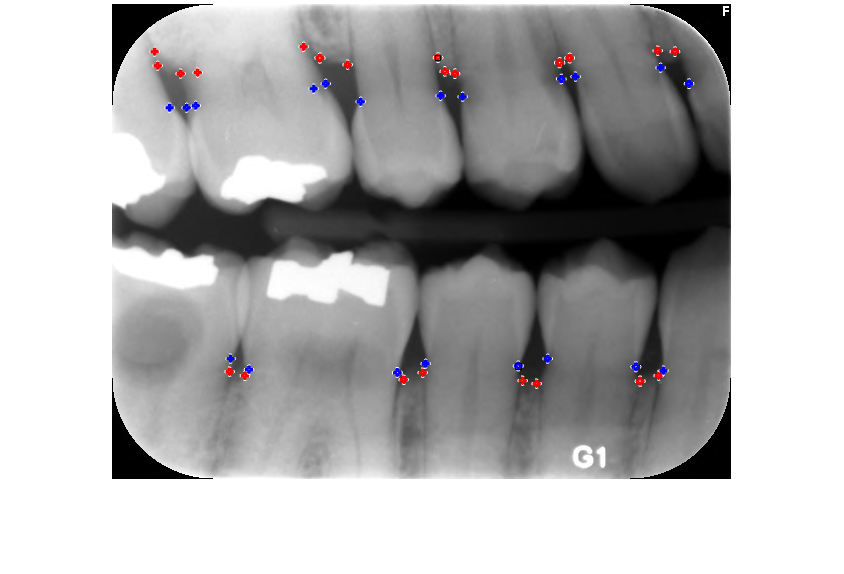

    centers = centers./3;
    radii = radii./3;
    centerRed = centerRed./3;
    radiiRed = radiiRed./3;     
imshow(rgb)
       hold on
 wBright = viscircles(centers, radii);
gright = viscircles(centerRed, radiiRed,'Color','b');


       
              rectangle("Position",[dotLabels.ABB{num}(1,1),dotLabels.ABB{num}(1,2),dotLabels.ABB{num}(1,3),dotLabels.ABB{num}(1,4),])
       rectangle("Position",[dotLabels.CEJ{num}(1,1),dotLabels.CEJ{num}(1,2),dotLabels.CEJ{num}(1,3),dotLabels.CEJ{num}(1,4),])
       hold off

% save("half_tooth_dot_labels4.mat","dotLabels")
% newDot = load("half_tooth_dot_labels4.mat")
% newDot = newDot.dotLabels;
% num = 20
%   rgb = imread(newDot.FileName{num});
% new = imresize(rgb,3);   
%         [~, yellowMasked] = YellowDotMask(new);
%         [~, redMasked] = RedDotColorMask(new);
% [centers,radii] = imfindcircles(yellowMasked,[10 20],'ObjectPolarity','bright','Sensitivity',0.97,'EdgeThreshold',0.5);
%         [centerRed, radiiRed] = imfindcircles(redMasked, [10 20], 'ObjectPolarity','bright','Sensitivity',0.97,'EdgeThreshold',0.2);
%         centers = centers./3;
%         radii = radii./3;
%         centerRed = centerRed./3;
%         radiiRed = radiiRed./3;
% imshow(rgb)
% wBright = viscircles(centers, radii);
% gright = viscircles(centerRed, radiiRed,'Color','b');


% coordinates_cropped_cell_orig_img = [dotLabels.ABB{1}(1,1),dotLabels.ABB{1}(1,2),dotLabels.ABB{1}(1,3),dotLabels.ABB{1}(1,4),];
%         cropped_cell_orig_img = imcrop(rgb, coordinates_cropped_cell_orig_img);
%        imshow(rgb)
%        hold on
%        rectangle("Position",[newDot.ABB{num}(1,1),newDot.ABB{num}(1,2),newDot.ABB{num}(1,3) + 2,newDot.ABB{num}(1,4) + 2,])
%        rectangle("Position",[newDot.CEJ{num}(1,1),newDot.CEJ{num}(1,2),newDot.CEJ{num}(1,3) + 2,newDot.CEJ{num}(1,4) + 2,])
%        hold off
%        imshow(rgb)
% imshow(redMasked)
%        imshow(yellowMasked)
% imshow(cropped_cell_orig_img)
